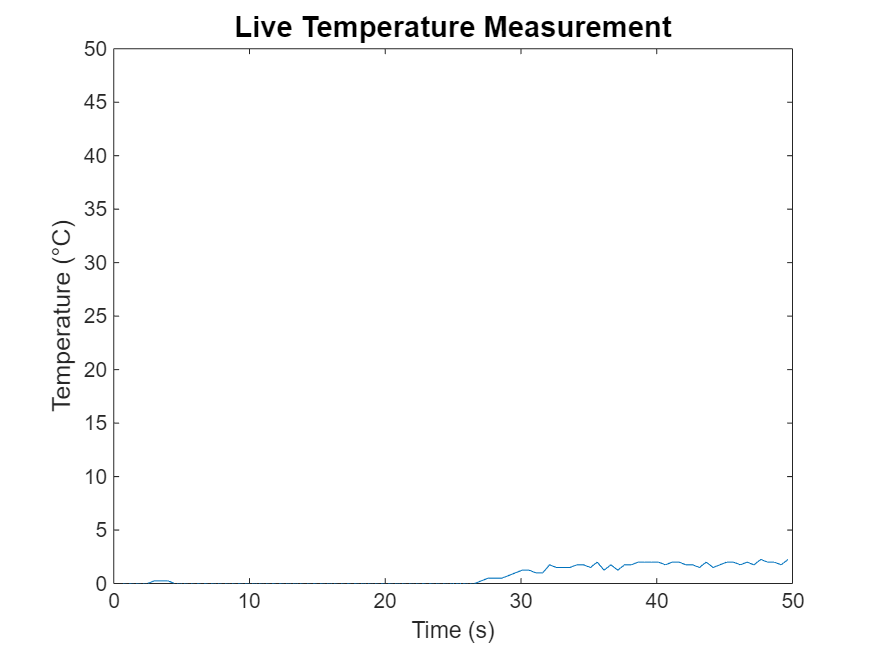

%% =========================================================================
%  MATLAB SCRIPT
%  Title      : Live USB Data Streaming and Temperature Plotting
%  Project    : Development of a Hydrogel Extruder (Mechatronic Project 478)
%  Name       : Simon Craig DANIEL
%  Student No : 25848887
%  Department : Mechanical and Mechatronic Engineering,
%               Stellenbosch University
%  Date       : 2025-08-20
%
%  Description:
%  -------------------------------------------------------------------------
%  This script establishes a USB serial connection between MATLAB and the
%  STM32 microcontroller. The STM32 streams thermocouple readings from the
%  MAX6675 over USB (CDC virtual COM port). The script:
%
%   • Opens a serial port to the STM32 board
%   • Reads incoming temperature packets in real-time
%   • Parses numeric data (or error strings such as "TC OPEN")
%   • Plots the temperature continuously in a live graph
%
%  Usage:
%   - Update the 'port' variable to match your COM port (e.g. "COM5").
%   - Run this script; it will start streaming and plotting immediately.
%   - Stop the script with Ctrl+C to close the port and exit cleanly.
%
%  Notes:
%   - Ensure MATLAB has permission to access the COM port.
%   - The STM32 must be programmed to transmit via USB CDC using
%     CDC_Transmit_FS().
%   - Sampling interval is determined by STM32 delay (e.g. 250 ms).
%
%  Version:
%   v1.0 – Initial implementation
%
%% =========================================================================
 
close all; clear;


port = "COM6"; 
baud = 115200;
s = serialport(port, baud);

i=1;
t0 = tic;   % start timer
while(1)
    a = readline(s);
    data(i) = sscanf(a, 'Temperature: %f C');
    time(i) = toc(t0);   % seconds since start

    % Plot Live Data
    plot(time, data);
    ylim([0 50]);
    title('Live Temperature Measurement','FontSize',14);
    ylabel('Temperature (°C)','FontSize',12);
    xlabel("Time (s)");
    grid on;

    pause(0.01);
    i = i+1;
end 